%Vehiculo
% salida yaw rate entrada steering
% El control está diseñado para considerar una velocidad lineal entre 4 y 10 m/s (circuito urbano)
% Fichero: paper2226.mat con K y Kred=balred(K,6). K es de orden 15
clear;
close all;

%System parameters
m=995;
a=1.233;
b=1.327;
Caf=41e3;
l=2.56;
Iz=1760;
Car=47e3;
g = 9.81;
%vx=6;
vx = ureal('vx',6,'Range',[4,10])

Uncertain real parameter "vx" with nominal value 6 and range [4,10].
Block Properties


a1=m*vx*a*Caf;
A1=m*a*Caf;
a2=l*Caf*Car;
A2=a2;
b1=m*vx*Iz;
B1=m*Iz;
b2=Iz*(Caf+Car)+m*((a^2)*Caf+(b^2)*Car);
B2=b2;
b3=(Caf*Car/vx)*(l^2)*(1+((m*vx*(b*Car-a*Caf))/(Caf*Caf*(l^2))));
B3=(Caf*Car)*(l^2)*(1+((m*vx*(b*Car-a*Caf))/(Caf*Caf*(l^2))));
s=tf('s');

p=(a1*s+a2)/(b1*s^2+b2*s+b3)%Proceso Continuo con incertidumbre

Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 8 states.
The model uncertainty consists of the following blocks:
  vx: Uncertain real, nominal = 6, range = [4,10], 4 occurrences
Model Properties



%analisis
Planta=tf(p) %Planta nominal


Planta =
 
     28.72 s + 469.5
  ---------------------
  s^2 + 28.48 s + 201.6
 
Continuous-time transfer function.
Model Properties


disp('Polos:'),pole(Planta)

Polos:


ans =   -15.3275
  -13.1530


disp('Ceros:'),tzero(p)

Ceros:


ans = -16.3456


%Perido de muestreo
T=10e-3;%10ms
load("paper2226.mat");
%K: regulador continuo de orden 15
%Kred: regulador continu de orden 6
BC1=minreal(K*Planta/(1+K*Planta));

18 states removed.


BC2=minreal(Kred*Planta/(1+Kred*Planta));

9 states removed.


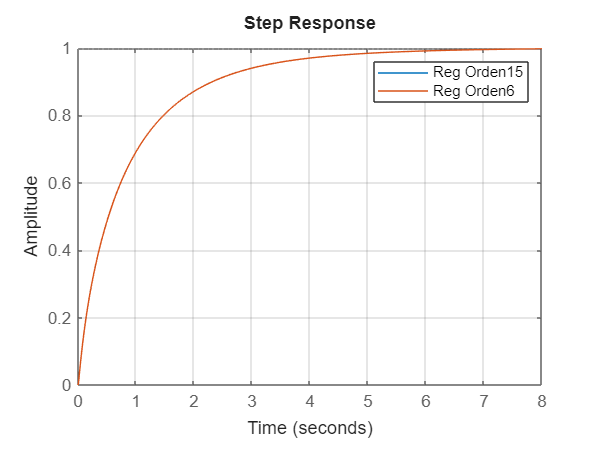

figure,step(BC1,BC2),legend('Reg Orden15','Reg Orden6'),grid

%No hay diferencias apreciables

Gr=c2d(K,T,'zoh');
SR_Diag=canon(Gr,'modal')


SR_Diag =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8         x9        x10        x11        x12        x13        x14        x15
   x1       0.217          0          0          0          0          0          0          0          0          0          0          0          0          0          0
   x2           0     0.8099     0.2434          0          0          0          0          0          0          0          0          0          0          0          0
   x3           0    -0.2434     0.8099          0          0          0          0          0          0          0          0          0          0          0          0
   x4           0          0          0     0.8542          0          0          0          0          0          0          0          0          0          0          0
   x5           0          0          0          0     0.9007    0.01961          0          0          0          0    

%%%%%%%%%%%%%%%%%%%%%
syms Z
G = tf(Gr);  % Convertir a simbólico
[num den]=tfdata(G,'v');
[r, p, k] = residue(num, den);
% Mostrar en pantalla
disp('Descomposición en fracciones simples:');
if ~isempty(k)
    fprintf('Término directo: %s\n', num2str(k));
end
for i = 1:length(r)
    if imag(r(i))==0
     fprintf('R%d/(z - P%d) = %.4f / (z - %.4f)\n', i, i, r(i), p(i));
    else
     fprintf('R%d/(z - P%d) = (%.4f+%.4f i) / (z - (%.4f+%.4f i))\n', i, i, real(r(i)),imag(r(i)), real(p(i)),imag(p(i)));
    end
end
%%%%%%%%%%%%%%%%%%%%%

[pole(SR_Diag) abs(pole(SR_Diag))]%Ordenador polos de mayor a menor rapidez

ans =    0.9966 + 0.0052i   0.9966 + 0.0000i
   0.9966 - 0.0052i   0.9966 + 0.0000i
   0.8099 + 0.2434i   0.8456 + 0.0000i
   0.8099 - 0.2434i   0.8456 + 0.0000i
   0.9007 + 0.0196i   0.9010 + 0.0000i
   0.9007 - 0.0196i   0.9010 + 0.0000i
   0.9970 + 0.0052i   0.9970 + 0.0000i
   0.9970 - 0.0052i   0.9970 + 0.0000i
   0.9693 + 0.0130i   0.9694 + 0.0000i
   0.9693 - 0.0130i   0.9694 + 0.0000i


diag(SR_Diag.A)

ans =     0.2170
    0.8099
    0.8099
    0.8542
    0.9007
    0.9007
    0.9653
    0.9693
    0.9693
    0.9833


p1=SR_Diag.A(1,1);%Real
p2p3=eig(SR_Diag.A(2:3,2:3));%Complejo
p4=SR_Diag.A(4,4);%Real
p5p6=eig(SR_Diag.A(5:6,5:6));%Complejo
p7=SR_Diag.A(7,7);%Real
p8p9=eig(SR_Diag.A(8:9,8:9));%Complejo
p10=SR_Diag.A(10,10);%Real
p11p12=eig(SR_Diag.A(11:12,11:12));%Complejo
p13p14=eig(SR_Diag.A(13:14,13:14));%Complejo
p15=SR_Diag.A(15,15);%Real Integrador
%Analisis de las 10 dinamicas
disp('[polo abs c*b ganancia]')

[polo abs c*b imag]


comp=[p1 abs(p1) norm(SR_Diag.C(:,1)*SR_Diag.B(1,:)) dcgain(tf(SR_Diag.C(:,1)*SR_Diag.B(1,:),[1 -p1],T))
 p2p3(1) abs(p2p3(1)) norm(SR_Diag.C(:,2:3)*SR_Diag.B(2:3,:)) dcgain(ss(SR_Diag.A(2:3,2:3),SR_Diag.B(2:3,:),SR_Diag.C(:,2:3),0,T))
 p4 abs(p4) norm(SR_Diag.C(:,4)*SR_Diag.B(4,:)) dcgain(tf(SR_Diag.C(:,4)*SR_Diag.B(4,:),[1 -p4],T))
 p5p6(1) abs(p5p6(1)) norm(SR_Diag.C(:,5:6)*SR_Diag.B(5:6,:)) dcgain(ss(SR_Diag.A(5:6,5:6),SR_Diag.B(5:6,:),SR_Diag.C(:,5:6),0,T))
 p7 abs(p7) norm(SR_Diag.C(:,7)*SR_Diag.B(7,:)) dcgain(tf(SR_Diag.C(:,7)*SR_Diag.B(7,:),[1 -p7],T))
 p8p9(1) abs(p8p9(1)) norm(SR_Diag.C(:,8:9)*SR_Diag.B(8:9,:)) dcgain(ss(SR_Diag.A(8:9,8:9),SR_Diag.B(8:9,:),SR_Diag.C(:,8:9),0,T))
 p10 abs(p10) norm(SR_Diag.C(:,10)*SR_Diag.B(10,:)) dcgain(tf(SR_Diag.C(:,10)*SR_Diag.B(10,:),[1 -p10],T))
 p11p12(1) abs(p11p12(1)) norm(SR_Diag.C(:,11:12)*SR_Diag.B(11:12,:)) dcgain(ss(SR_Diag.A(11:12,11:12),SR_Diag.B(11:12,:),SR_Diag.C(:,11:12),0,T))
 p13p14(1) abs(p13p14(1)) norm(SR_Diag.C(:,13:14)*SR_Diag.B(13:14,:)) dcgain(ss(SR_Diag.A(13:14,13:14),SR_Diag.B(13:14,:),SR_Diag.C(:,13:14),0,T))
 p15 abs(p15) norm(SR_Diag.C(:,15)*SR_Diag.B(15,:)) dcgain(tf(SR_Diag.C(:,15)*SR_Diag.B(15,:),[1 -p15],T))]

ans =    0.2170 + 0.0000i   0.2170 + 0.0000i   0.0498 + 0.0000i   0.0000 + 0.0000i
   0.8099 + 0.2434i   0.8456 + 0.0000i   0.0000 + 0.0000i   0.2434 + 0.0000i
   0.8542 + 0.0000i   0.8542 + 0.0000i   0.0001 + 0.0000i   0.0000 + 0.0000i
   0.9007 + 0.0196i   0.9010 + 0.0000i   0.0007 + 0.0000i   0.0196 + 0.0000i
   0.9653 + 0.0000i   0.9653 + 0.0000i   0.0004 + 0.0000i   0.0000 + 0.0000i
   0.9693 + 0.0130i   0.9694 + 0.0000i   0.0004 + 0.0000i   0.0130 + 0.0000i
   0.9833 + 0.0000i   0.9833 + 0.0000i   0.0010 + 0.0000i   0.0000 + 0.0000i
   0.9966 + 0.0052i   0.9966 + 0.0000i   0.0000 + 0.0000i   0.0052 + 0.0000i
   0.9970 + 0.0052i   0.9970 + 0.0000i   0.0001 + 0.0000i   0.0052 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   0.0046 + 0.0000i   0.0000 + 0.0000i


%p1 a p15 ordenados por rapidez
%p1=0.217
%p2p3=0.8099+-0.2434j
%p4=0.8542
%p5p6=0.9007+-0.0196j

%p7=0.9653
%p8p9=0.9693+-0.013j
%p10=0.9833

%p11p12=0.9966+-0.0052j
%p13p14=0.997+-0.0052j
%p15=1
%Ordenados por ganancia (c*b) residuo
%[p1 p15 p10 p5p6 p7 p10 p9 p3 p8 p2]
%Analisis modelo balanceado
[SR_Bal gr]=balreal(Gr)


SR_Bal =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15
   x1            1  -6.238e-05     2.4e-05   4.235e-08  -1.196e-06   7.921e-07   3.687e-08   5.533e-08   9.757e-08   2.704e-09   4.092e-08   1.956e-08  -2.473e-09   2.137e-09   6.051e-10
   x2   -6.238e-05       0.418      0.3295    0.004001    -0.04803     0.03812    0.001905    0.002881    0.005076   0.0001403    0.002124    0.001015  -0.0001284   0.0001109   3.141e-05
   x3      2.4e-05      0.3295      0.7921   -0.004021     0.04099    -0.03392   -0.001721   -0.002607   -0.004592  -0.0001268   -0.001921  -0.0009179   0.0001161  -0.0001003   -2.84e-05
   x4   -4.235e-08   -0.004001    0.004021      0.9999    0.006717   -0.002634  -0.0001108  -0.0001648  -0.0002909  -8.091e-06  -0.0001223  -5.851e-05   7.394e-06   -6.39e-06   -1.81e-06
   x5   -1.196e-06    -0.04803     0.04099   -

g =   231.2949
    0.0591
    0.0351
    0.0057
    0.0032
    0.0008
    0.0000
    0.0000
    0.0000
    0.0000


disp('[polo gan]')

[polo gan]


[pole(SR_Bal) gr]

ans = 1.0e+02 *

   0.0022 + 0.0000i   2.3129 + 0.0000i
   0.0081 + 0.0024i   0.0006 + 0.0000i
   0.0081 - 0.0024i   0.0004 + 0.0000i
   0.0085 + 0.0000i   0.0001 + 0.0000i
   0.0090 + 0.0002i   0.0000 + 0.0000i
   0.0090 - 0.0002i   0.0000 + 0.0000i
   0.0097 + 0.0000i   0.0000 + 0.0000i
   0.0097 + 0.0001i   0.0000 + 0.0000i
   0.0097 - 0.0001i   0.0000 + 0.0000i
   0.0098 + 0.0000i   0.0000 + 0.0000i


%Ordenados por gr (gramiano)
%[p1 p2p3 p4 p5p6 p7 p8p9 p10 p13p14 p11p12]
 
%Prueba para N=2
N=2;
GrN2=d2d(Gr,T*N);%Discreto a periodo lento

%Forma diagonal
nr=6;%2 reales y 4 complejos
nl=[4 5];%(2reales 2complejos) + (1real 4complejos)
%Reduce el orden de 15 a 11-10
[RegDiag_sep]=regdiagsep(SR_Diag, [nr nl]);%separar subespacios
RegDiag_Rap=RegDiag_sep.S1;
RegDiag_Len1=RegDiag_sep.S2;
RegDiag_Len1.D=0;
RegDiag_Len1_ext=d2d(RegDiag_Len1,N*T);
RegDiag_Len2=RegDiag_sep.S3;
RegDiag_Len2.D=0;
RegDiag_Len2_ext=d2d(RegDiag_Len2,N*T);


%A partir de la forma balanceada, subiremos N progresivamente intentando dejar el menor
% orden posible en la parte rápida y el resto a las partes lentas

%Forma balanceada
[RegBal_sep]=regsep(SR_Bal,[nr nl]);%[nr nl1 nl2]
RegBal_Rap=RegBal_sep.S1;
RegBal_Len1=RegBal_sep.S2;
RegBal_Len1_ext=d2d(RegBal_Len1,N*T);
RegBal_Len2=RegBal_sep.S3;
RegBal_Len2_ext=d2d(RegBal_Len2,N*T);


sim('PruebaN2');

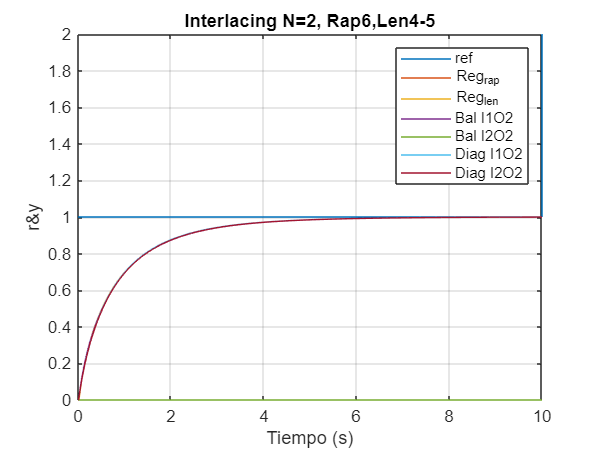

f=figure;
set(f,'Name','Interlacing N=2, Rap6,Len4-5')
plot(datos.time,datos.signals.values),ylabel('r&y'),xlabel('Tiempo (s)'),grid
title('Interlacing N=2, Rap6,Len4-5');
legend('ref','Reg_{rap}','Reg_{len}','Bal I1O2','Bal I2O2','Diag I1O2', 'Diag I2O2')

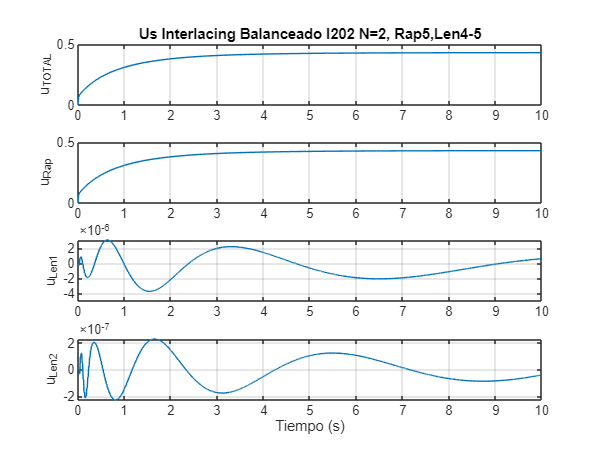


f=figure;
set(f,'Name','U Interlacing Balanceado I202 N=2, Rap6,Len4-5')
subplot(411),plot(Us.time,Us.signals(1).values),ylabel('u_{TOTAL}'),grid;
title('Us Interlacing Balanceado I202 N=2, Rap5,Len4-5');
subplot(412),plot(Us.time,Us.signals(2).values),ylabel('u_{Rap}'),grid;
subplot(413),plot(Us.time,Us.signals(3).values),ylabel('u_{Len1}'),grid;
subplot(414),plot(Us.time,Us.signals(4).values),ylabel('u_{Len2}'),grid;xlabel('Tiempo (s)'),

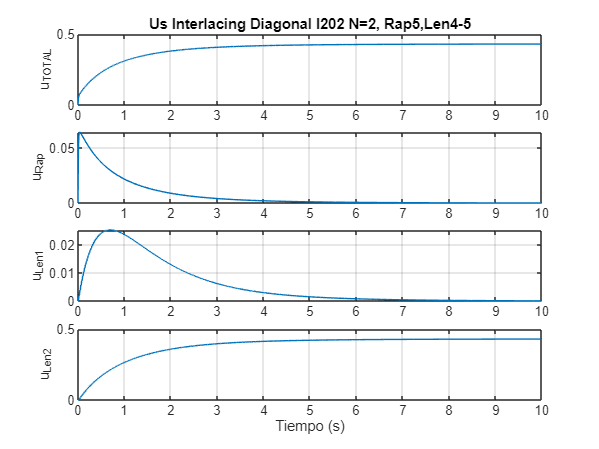

f=figure;
set(f,'Name','U Interlacing Diagonal I202 N=2, Rap6,Len4-5')
subplot(411),plot(UsDiag.time,UsDiag.signals(1).values),ylabel('u_{TOTAL}'),grid;
title('Us Interlacing Diagonal I202 N=2, Rap5,Len4-5');
subplot(412),plot(UsDiag.time,UsDiag.signals(2).values),ylabel('u_{Rap}'),grid;
subplot(413),plot(UsDiag.time,UsDiag.signals(3).values),ylabel('u_{Len1}'),grid;
subplot(414),plot(UsDiag.time,UsDiag.signals(4).values),ylabel('u_{Len2}'),grid;xlabel('Tiempo (s)'),



%Prueba para N=3
N=3;
GrN3=d2d(Gr,T*N);%Discreto a periodo lento

%Forma diagonal
nr=4;%2 reales y 2 complejos
nl=[4 3 4];%(2reales 2complejos) + (1real 2complejos) + (4complejos)
%Reduce el orden de 15 a 8-7
[RegDiag_sep]=regdiagsep(SR_Diag, [nr 3 3 4 1]);%separar subespacios
%El nl4 (integrador) lo juntamos con nl1
RegDiag_Rap=RegDiag_sep.S1;
RegDiag_Len1=ss(blkdiag(RegDiag_sep.S2.A,RegDiag_sep.S5.A),[RegDiag_sep.S2.B;RegDiag_sep.S5.A],[RegDiag_sep.S2.C RegDiag_sep.S5.C],0,T);
RegDiag_Len1_ext=d2d(RegDiag_Len1,N*T);
RegDiag_Len2=RegDiag_sep.S3;
RegDiag_Len2_ext=d2d(RegDiag_Len2,N*T);
RegDiag_Len3=RegDiag_sep.S4;
RegDiag_Len3_ext=d2d(RegDiag_Len3,N*T);


%A partir de la forma balanceada, subiremos N progresivamente intentando dejar el menor
% orden posible en la parte rápida y el resto a las partes lentas

%Forma balanceada
[RegBal_sep]=regsep(SR_Bal,[nr nl]);%[nr nl1 nl2 nl3]
RegBal_Rap=RegBal_sep.S1;
RegBal_Len1=RegBal_sep.S2;
RegBal_Len1_ext=d2d(RegBal_Len1,N*T);
RegBal_Len2=RegBal_sep.S3;
RegBal_Len2_ext=d2d(RegBal_Len2,N*T);
RegBal_Len3=RegBal_sep.S4;
RegBal_Len3_ext=d2d(RegBal_Len3,N*T);


sim('PruebaN3');

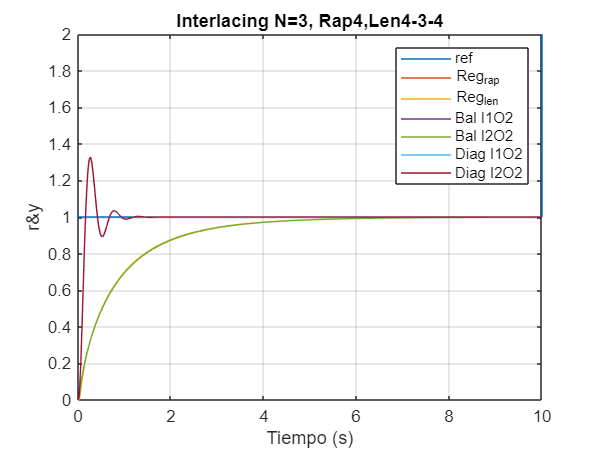

f=figure;
set(f,'Name','Interlacing N=3, Rap4,Len4-3-4')
plot(datos.time,datos.signals.values),ylabel('r&y'),xlabel('Tiempo (s)'),grid
title('Interlacing N=3, Rap4,Len4-3-4');
legend('ref','Reg_{rap}','Reg_{len}','Bal I1O2','Bal I2O2','Diag I1O2', 'Diag I2O2')

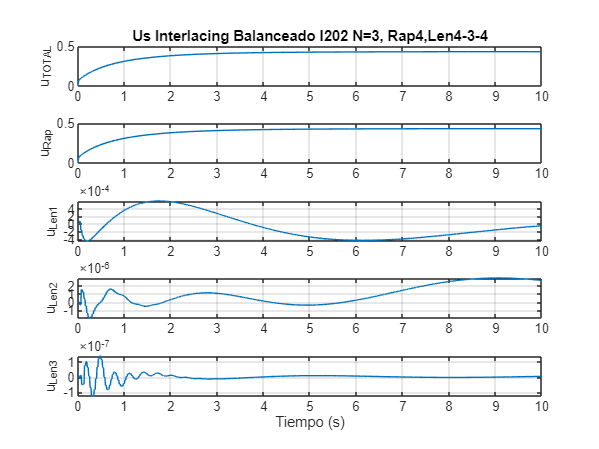


f=figure;
set(f,'Name','U Interlacing Balanceado I202 N=3, Rap4,Len4-3-4')
subplot(511),plot(Us.time,Us.signals(1).values),ylabel('u_{TOTAL}'),grid;
title('Us Interlacing Balanceado I202 N=3, Rap4,Len4-3-4');
subplot(512),plot(Us.time,Us.signals(2).values),ylabel('u_{Rap}'),grid;
subplot(513),plot(Us.time,Us.signals(3).values),ylabel('u_{Len1}'),grid;
subplot(514),plot(Us.time,Us.signals(4).values),ylabel('u_{Len2}'),grid;
subplot(515),plot(Us.time,Us.signals(5).values),ylabel('u_{Len3}'),grid;
xlabel('Tiempo (s)'),

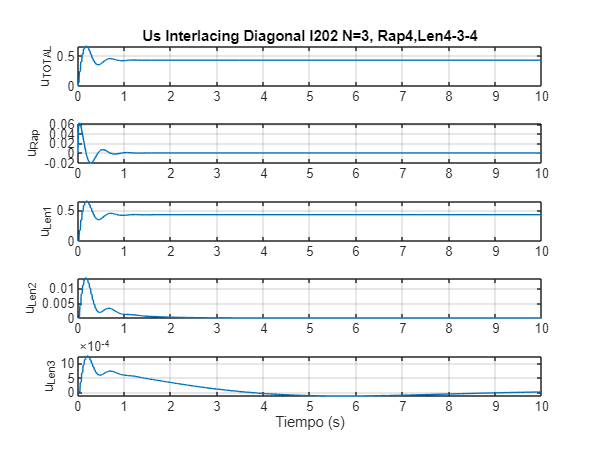

f=figure;
set(f,'Name','U Interlacing Diagonal I202 N=3, Rap4,Len4-3-4')
subplot(511),plot(UsDiag.time,UsDiag.signals(1).values),ylabel('u_{TOTAL}'),grid;
title('Us Interlacing Diagonal I202 N=3, Rap4,Len4-3-4');
subplot(512),plot(UsDiag.time,UsDiag.signals(2).values),ylabel('u_{Rap}'),grid;
subplot(513),plot(UsDiag.time,UsDiag.signals(3).values),ylabel('u_{Len1}'),grid;
subplot(514),plot(UsDiag.time,UsDiag.signals(4).values),ylabel('u_{Len2}'),grid;
subplot(515),plot(UsDiag.time,UsDiag.signals(5).values),ylabel('u_{Len3}'),grid;
xlabel('Tiempo (s)'),

%N=3 Diagonal funciona peor. Se puede probar a cambiar el orden o añadir
%más dinámicas a la parte rápida.
